# Best dynamically feasible path using the sequence from City_sequence.mlx

**OBJECTIVE:**

The goal of this code is to compute a time-optimal, dynamically feasible path that visits all 10 cities in the order prescribed by City_sequence.mlx, starting from one of the corners of a 10x10 box, in this case starting at the origin. The vehicle is modeled with bounded steering rate and acceleration, so not every geometric path is allowed. Instead, the path must satisfy the vehicle dynamics while minimizing total travel time.

**DESCRIPTION:**

This script constructs a minimum-time trajectory through the cities using an optimal control formulation. The vehicle state is

- position: $(x(t), y(t))$

- heading: $\theta(t)$

- speed: $v(t)$

with control inputs

- steering rate: $\gamma(t)$

- longitudinal acceleration: $a(t)$

The dynamics are


$$\dot{x} = v\cos\theta,\quad
\dot{y} = v\sin\theta,\quad
\dot{\theta} = \gamma,\quad
\dot{v} = a
$$


with bounded controls $|\gamma| \le 1$ and $|a| \le 1$. The parameter $r$ controls the penalty on control effort through the Hamiltonian, so that large steering and acceleration are discouraged.

The problem is posed as a multi-arc boundary value problem (BVP), where each “arc” connects two consecutive cities in the fixed sequence


$$\text{origin} \rightarrow 10 \rightarrow 2 \rightarrow 1 \rightarrow 4 \rightarrow 3 \rightarrow 8 \rightarrow 6 \rightarrow 9 \rightarrow 7 \rightarrow 5$$


For each arc, the states and costates must satisfy the optimality conditions (Pontryagin’s Minimum Principle), including continuity of states, appropriate jump/continuity conditions on costates, and a zero-Hamiltonian transversality condition along the optimal trajectory.

The cost being minimized is the total travel time plus a regularization on control effort encoded via the Hamiltonian:


$$J = \int_0^{t_f} 1 + \frac1r (\gamma ^2 + a^2)\: dt$$


where the control penalty is handled internally in the Hamiltonian:


$$H = 1 + \frac{1}{r}(\gamma^2 + a^2) + \lambda_x v\cos\theta + \lambda_y v\sin\theta + \lambda_\theta \gamma + \lambda_v a$$


The cost for the assignment is represented by the total number of cities times 10, minus the time it takes to reach the tenth and last city:


$$J = 10n - t_f$$


where $n$ is the number of cities visited, and $t_f$ is the final time at the end of the last arc.

There are two values that represent the cost, $J$, in this project. The relevant cost to the code is the first definition of $J$.

**NUMERICAL APPROACH:**

The solution is built incrementally in five stages:

- Path 1 – 2 Cities (origin → city 10 → city 2): A genetic algorithm (GA) (`fun1`) first searches over the initial costates and arc durations to generate a good initial guess that approximately hits the intermediate and final cities while driving the Hamiltonian and terminal costates toward zero. This guess is then refined using `bvp4c` on a two-arc system.

- Path 2 – 4 Cities, Path 3 – 6 Cities, Path 4 – 8 Cities, Path 5 – 10 Cities: For each additional pair of cities, another GA call (`fun2`) extends the trajectory by optimizing the costates and durations for the next two arcs, starting from the terminal state of the previous solution. The resulting approximate solution is used to initialize a larger multi-arc BVP solved by `bvp4c` via `ODEmain` and `bcfunc`.

- Homotopy Step at 6 Cities:At the 6-city stage, a modified boundary condition function `homotopycity6` is used to impose an additional heading constraint with $\theta$ just before one of the cities. This acts as a homotopy step to help the solver converge to a more physically reasonable trajectory (e.g., limiting the heading at that point).

Across all stages, the boundary condition functions enforce:

- initial conditions at the origin (position, heading, and speed),

- city-hitting constraints at each intermediate city,

- continuity of states and costates between arcs,

- terminal conditions at the last city, including Hamiltonian and costate conditions.

At the end, the script:

- plots the full optimal trajectory across all 10 cities, showing each arc and the city locations,

- computes the total travel time by summing the optimal arc durations stored in `sol5.parameters`, and

- packages the final solution (trajectory, city sequence, and parameter (r)) into a `solution` struct for later use in Final_solution.mlx

clear; 
close all;
clc;

r = 0.5; % Want r small to start to make it easier for the solver, will iterate with larger r values after a solution is found

origin = [0, 0];
city1 = [8.5, 4.2];
city2 = [6.2, 0.5];
city3 = [3.5, 9.0];
city4 = [5.1, 9.4];
city5 = [4.0, 4.9];
city6 = [0.8, 4.9];
city7 = [2.4, 3.4];
city8 = [1.2, 9.0];
city9 = [1.8, 3.7];
city10 = [2.4, 1.1];

% City path order: origin, 10, 2, 1, 4, 3, 8, 6, 9, 7, 5
city_sequence = [city10; city2; city1; city4; city3; city8; city6; city9; city7; city5]';

## Path 1 - 2 Cities

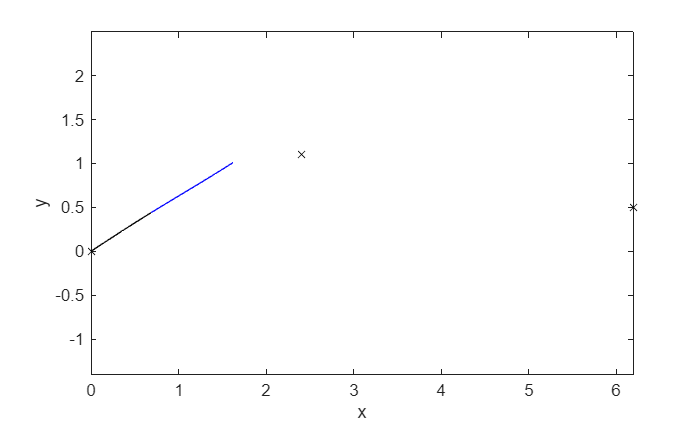

P0 = origin;
P1 = city10;
P2 = city2;

load("x_path1.mat");
% x_path1 = ga(@(x)fun1(x,r,P0,P1,P2),8,[],[],[],[],[0, -1, -1, -2, 0.5, -1,-1, 0.5 ],[2,1, 1, 1, 4, 1, 1, 4])  % no inequality or equality constraints 


% Plotting the trajectory to make sure the GA works

[~, S1_1] = ode45(@(t,s)ODEs(t,s,r), linspace(0,x_path1(5),11), [P0(1),P0(2), x_path1(1), 0, x_path1(2), x_path1(3), 0, x_path1(4)]); 
[~, S1_2] = ode45(@(t,s)ODEs(t,s,r), linspace(0,x_path1(8),11), [S1_1(end,1:4), x_path1(6), x_path1(7), S1_1(end, 7:8)]);


figure 
plot(S1_1(:,1), S1_1(:,2), '-k', S1_2(:,1), S1_2(:, 2), '-b', [P0(1),P1(1),P2(1)], [P0(2),P1(2),P2(2)], 'xk')
xlabel('x')
ylabel('y')
axis equal

Because r is so small, it takes too long to accelerate to an amount where the cities can actually be reached.

sol1init.x = linspace(0,1,11); % don't want too big of arrays, 11 mesh points is good
sol1init.y = [S1_1, S1_2]'; % transpose so this is all in row vectors (16 rows (states for 2 arcs), 11 col (mesh points), (16x11)
sol1init.parameters = [x_path1(5), x_path1(8)]; % these are the time durations for each leg of the path

con1 = bcfunc(sol1init.y(:,1), sol1init.y(:,end), sol1init.parameters, r, city_sequence)' % checking the constraints to ensure they are close to zero.

con1 =          0
         0
         0
         0
   -1.7114
   -0.6588
         0
         0
         0
         0
         0
         0
    0.7130
   -4.5772
    0.5111


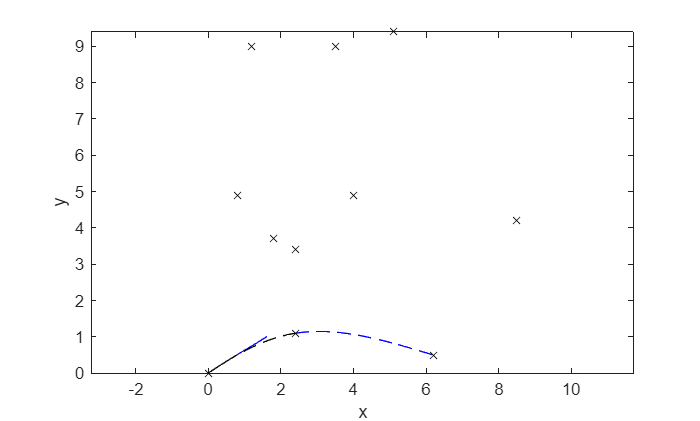

% This indicates a good solution

sol1 = bvp4c(@(t,s,times)ODEmain(t,s,times,r), @(so,sf,times)bcfunc(so,sf,times,r,city_sequence), sol1init); % Using bvp4c to compute a solution, 
% using the GA guess


% Plotting the bvp4c solution
hold on
plot(sol1.y(1,:), sol1.y(2,:), '--k', sol1.y(9,:), sol1.y(10,:), '--b',city_sequence(1,1:10),city_sequence(2,1:10),'xk')

Although the GA guess wasn't great, it was good enough for the solver to find a solution. 

## Path 2 - 4 Cities

After the first two cities, the following increments of two cities at a time follow a very similar structure.

sol2init = sol1;

P0 = city2;
P1 = city1;
P2 = city4;

load x_path2.mat
% x_path2 = ga(@(x)fun2(x,r,sol1,P1,P2),6,[],[],[],[],[-1, -1, 0.5, -1, -1, 0.5],[1, 1, 4, 1, 1, 4]);

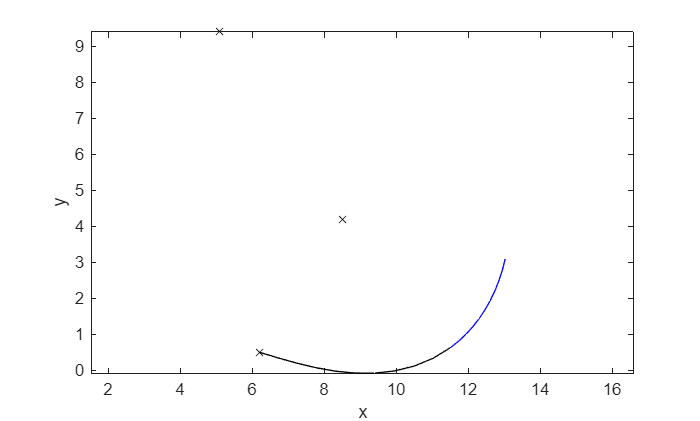

[~, S2_1] = ode45(@(t,s)ODEs(t,s,r), linspace(0,x_path2(3),11), [sol1.y(end-7,end), sol1.y(end-6,end), sol1.y(end-5,end), ...
    sol1.y(end-4,end), x_path2(1), x_path2(2), sol1.y(end-1,end), sol1.y(end,end)]); 
[~, S2_2] = ode45(@(t,s)ODEs(t,s,r), linspace(0,x_path2(6),11), [S2_1(end,1:4), x_path2(4), x_path2(5), S2_1(end,7:8)]);

figure
plot(S2_1(:,1), S2_1(:,2), '-k', S2_2(:,1), S2_2(:, 2), '-b', [P0(1),P1(1),P2(1)], [P0(2),P1(2),P2(2)], 'xk')
xlabel('x')
ylabel('y')
axis equal

### Combining Leg 1 BVP4C with Leg 2 GA

This appends the GA guess for the third and fourth city to the solution generated by bvp4c for the first two cities. This combined path will serve as the guess for the next bvp4c.

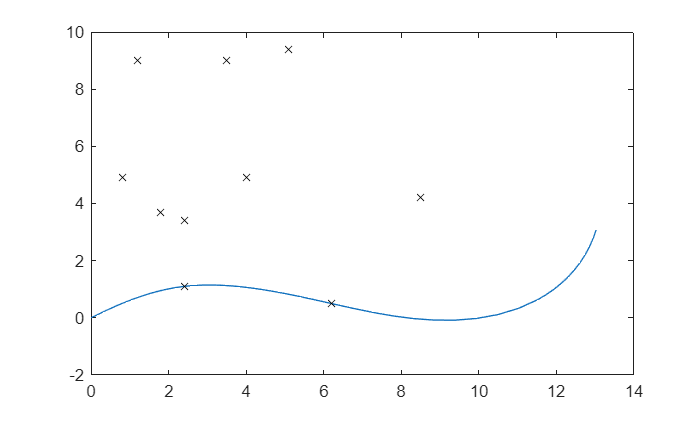

Guess2_x = [sol1.y(1,:)'; sol1.y(9,:)'; S2_1(:,1); S2_2(:,1)];
Guess2_y = [sol1.y(2,:)'; sol1.y(10,:)'; S2_1(:,2); S2_2(:,2)];

figure
plot(Guess2_x,Guess2_y,city_sequence(1,1:10),city_sequence(2,1:10),'xk')

% Using interp1 to match mesh points since they are inconsistent
t_old = linspace(0,1,length(sol1.x));
t_new = linspace(0,1,11);

sol1_part1 = interp1(t_old,sol1.y(1:8,:)',t_new)';
sol1_part2 = interp1(t_old,sol1.y(9:16,:)',t_new)';

sol2init.x = linspace(0,1,11);
sol2init.y = [sol1_part1; sol1_part2; S2_1'; S2_2'];
% sol2init.y = [sol1.y(1:8,:); sol1.y(9:16,:); S2_1'; S2_2'];
sol2init.parameters = [sol1.parameters', x_path2(3), x_path2(6)];

con2 = bcfunc(sol2init.y(:,1), sol2init.y(:,end), sol2init.parameters, r, city_sequence)' 

con2 =          0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
    0.0000
         0
         0


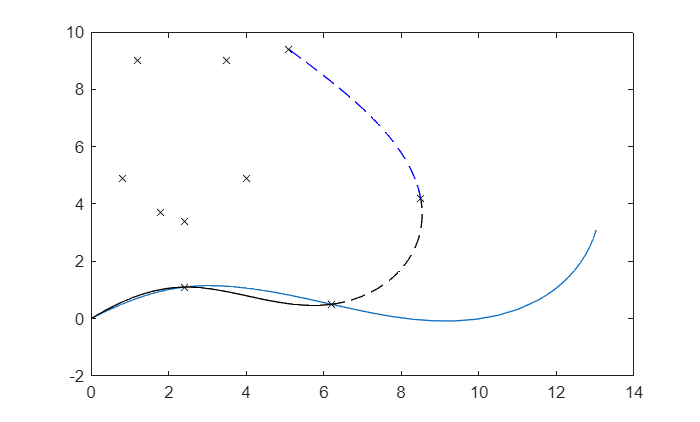

sol2 = bvp4c(@(t,s,times)ODEmain(t,s,times,r), @(so,sf,times)bcfunc(so,sf,times,r,city_sequence), sol2init);

hold on
plot(sol2.y(1,:), sol2.y(2,:), '-k', sol2.y(9,:), sol2.y(10,:), '-k', sol2.y(17,:), sol2.y(18,:), '--k', sol2.y(25,:), sol2.y(26,:), '--b')

## Path 3 - 6 Cities

From here on out, each leg of two cities follows the exact same process as path 2 (4 cites).

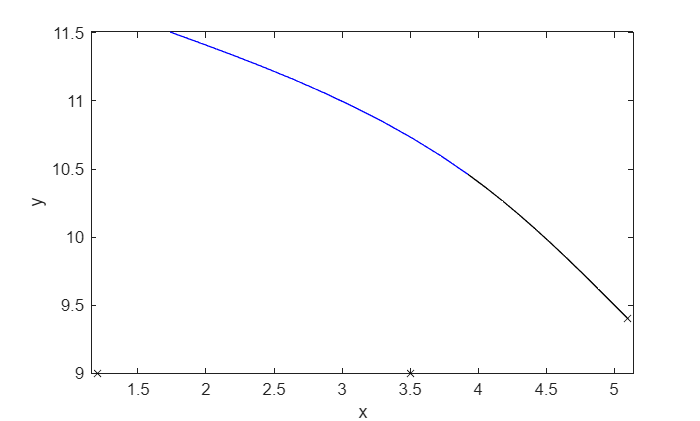

sol3init = sol2;

P0 = city4;
P1 = city3;
P2 = city8;

load x_path3.mat
% x_path3 = ga(@(x)fun2(x,r,sol2,P1,P2),6,[],[],[],[],[-1, -1, 0.5, -1, -1, 0.5],[1, 1, 4, 1, 1, 4]);

[~, S3_1] = ode45(@(t,s)ODEs(t,s,r), linspace(0,x_path3(3),11), [sol2.y(end-7,end), sol2.y(end-6,end), sol2.y(end-5,end), ...
    sol2.y(end-4,end), x_path3(1), x_path3(2), sol2.y(end-1,end), sol2.y(end,end)]); 
[~, S3_2] = ode45(@(t,s)ODEs(t,s,r), linspace(0,x_path3(6),11), [S3_1(end,1:4), x_path2(4), x_path3(5), S3_1(end,7:8)]);

figure
plot(S3_1(:,1), S3_1(:,2), '-k', S3_2(:,1), S3_2(:, 2), '-b', [P0(1),P1(1),P2(1)], [P0(2),P1(2),P2(2)], 'xk')
xlabel('x')
ylabel('y')
axis equal

% Appending the GA guess to the previous bvp4c solution
Guess3_x = [sol2.y(1,:)'; sol2.y(9,:)'; sol2.y(17,:)'; sol2.y(25,:)'; S3_1(:,1); S3_2(:,1)];
Guess3_y = [sol2.y(2,:)'; sol2.y(10,:)'; sol2.y(18,:)'; sol2.y(26,:)'; S3_1(:,2); S3_2(:,2)];

figure
plot(Guess3_x,Guess3_y,city_sequence(1,1:10),city_sequence(2,1:10),'xk')

t_old = linspace(0,1,length(sol2.x));
t_new = linspace(0,1,11);

sol2_part1 = interp1(t_old,sol2.y(1:8,:)',t_new)';
sol2_part2 = interp1(t_old,sol2.y(9:16,:)',t_new)';
sol2_part3 = interp1(t_old,sol2.y(17:24,:)',t_new)';
sol2_part4 = interp1(t_old,sol2.y(25:32,:)',t_new)';

sol3init.x = linspace(0,1,11);
sol3init.y = [sol2_part1; sol2_part2; sol2_part3; sol2_part4; S3_1'; S3_2'];
sol3init.parameters = [sol2.parameters', x_path3(3), x_path3(6)];

% This is where we use homotopycity6 instead of bcfunc to constrain theta(t6-)
con3 = homotopycity6(sol3init.y(:,1), sol3init.y(:,end), sol3init.parameters, r, city_sequence)' 

con3 =          0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
   -0.0000
         0
         0


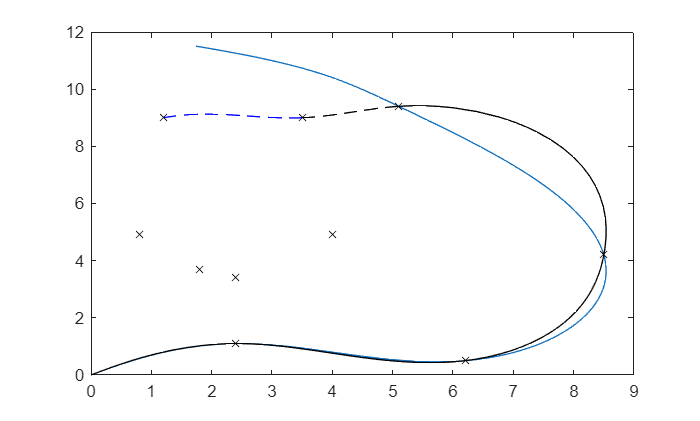

sol3 = bvp4c(@(t,s,times)ODEmain(t,s,times,r), @(so,sf,times)homotopycity6(so,sf,times,r,city_sequence), sol3init);

hold on
plot(sol3.y(1,:), sol3.y(2,:), '-k', sol3.y(9,:), sol3.y(10,:), '-k', sol3.y(17,:), sol3.y(18,:), '-k', sol3.y(25,:), sol3.y(26,:), '-k', ...
    sol3.y(33,:), sol3.y(34,:), '--k', sol3.y(41,:), sol3.y(42,:), '--b')

## Path 4 - 8 Cities

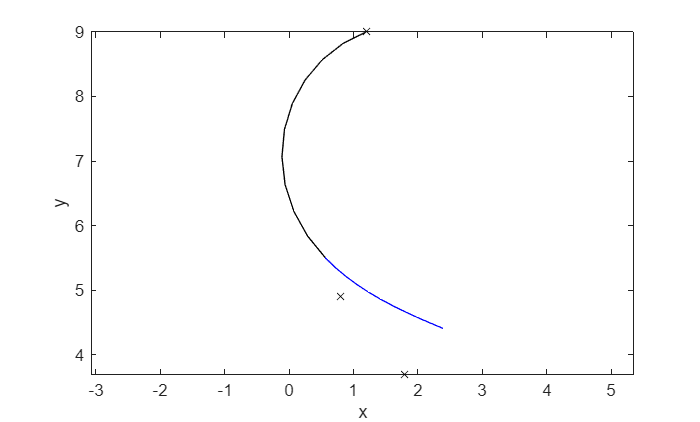

sol4init = sol3;

P0 = city8;
P1 = city6;
P2 = city9;

load x_path4.mat
% x_path4 = ga(@(x)fun2(x,r,sol3,P1,P2),6,[],[],[],[],[-1, -1, 0.5, -1, -1, 0.5],[1, 1, 4, 1, 1, 4]);

[~, S4_1] = ode45(@(t,s)ODEs(t,s,r), linspace(0,x_path4(3),11), [sol3.y(end-7,end), sol3.y(end-6,end), sol3.y(end-5,end), ...
    sol3.y(end-4,end), x_path4(1), x_path4(2), sol3.y(end-1,end), sol3.y(end,end)]); 
[~, S4_2] = ode45(@(t,s)ODEs(t,s,r), linspace(0,x_path4(6),11), [S4_1(end,1:4), x_path4(4), x_path4(5), S4_1(end,7:8)]);

figure
plot(S4_1(:,1), S4_1(:,2), '-k', S4_2(:,1), S4_2(:, 2), '-b', [P0(1),P1(1),P2(1)], [P0(2),P1(2),P2(2)], 'xk')
xlabel('x')
ylabel('y')
axis equal

Guess4_x = [sol3.y(1,:)'; sol3.y(9,:)'; sol3.y(17,:)'; sol3.y(25,:)'; sol3.y(33,:)'; sol3.y(41,:)'; S4_1(:,1); S4_2(:,1)];
Guess4_y = [sol3.y(2,:)'; sol3.y(10,:)'; sol3.y(18,:)'; sol3.y(26,:)'; sol3.y(34,:)'; sol3.y(42,:)'; S4_1(:,2); S4_2(:,2)];

figure
plot(Guess4_x,Guess4_y,city_sequence(1,1:10),city_sequence(2,1:10),'xk')

t_old = linspace(0,1,length(sol3.x));
t_new = linspace(0,1,11);

sol3_part1 = interp1(t_old,sol3.y(1:8,:)',t_new)';
sol3_part2 = interp1(t_old,sol3.y(9:16,:)',t_new)';
sol3_part3 = interp1(t_old,sol3.y(17:24,:)',t_new)';
sol3_part4 = interp1(t_old,sol3.y(25:32,:)',t_new)';
sol3_part5 = interp1(t_old,sol3.y(33:40,:)',t_new)';
sol3_part6 = interp1(t_old,sol3.y(41:48,:)',t_new)';


sol4init.x = linspace(0,1,11);
sol4init.y = [sol3_part1; sol3_part2; sol3_part3; sol3_part4; sol3_part5; sol3_part6; S4_1'; S4_2'];
sol4init.parameters = [sol3.parameters', x_path4(3), x_path4(6)];

con4 = bcfunc(sol4init.y(:,1), sol4init.y(:,end), sol4init.parameters, r, city_sequence)' 

con4 =          0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
   -0.0000
         0
         0


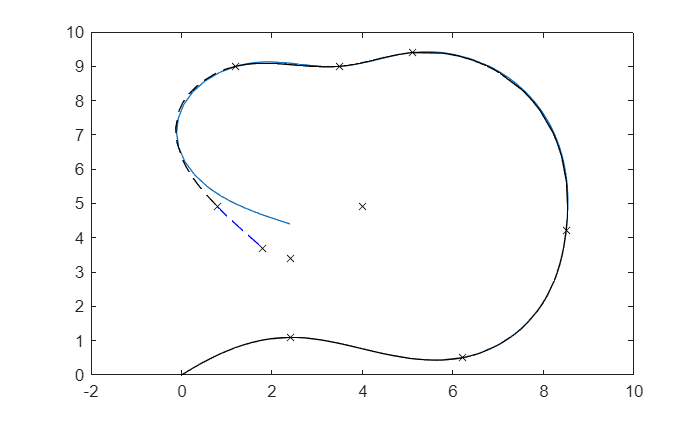

sol4 = bvp4c(@(t,s,times)ODEmain(t,s,times,r), @(so,sf,times)bcfunc(so,sf,times,r,city_sequence), sol4init);

hold on
plot(sol4.y(1,:), sol4.y(2,:), '-k', sol4.y(9,:), sol4.y(10,:), '-k', sol4.y(17,:), sol4.y(18,:), '-k', sol4.y(25,:), sol4.y(26,:), '-k', ...
    sol4.y(33,:), sol4.y(34,:), '-k', sol4.y(41,:), sol4.y(42,:), '-k', sol4.y(49,:), sol4.y(50,:), '--k', sol4.y(57,:), sol4.y(58,:), '--b')

## Path 5 - 10 Cities

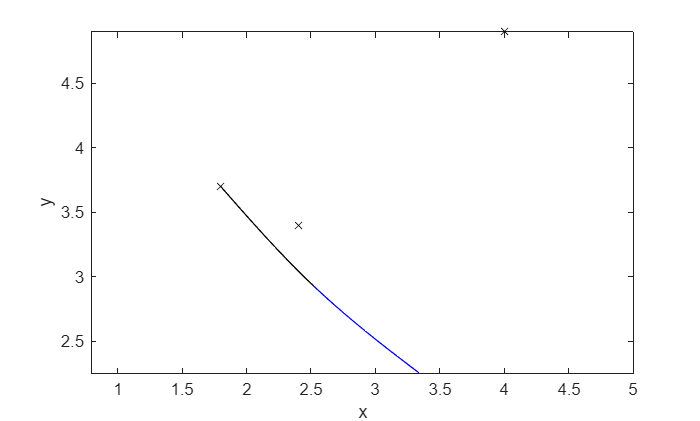

sol5init = sol4;

P0 = city9;
P1 = city7;
P2 = city5;

load x_path5.mat
% x_path5 = ga(@(x)fun2(x,r,sol4,P1,P2),6,[],[],[],[],[-1, -1, 0.5, -1, -1, 0.5],[1, 1, 4, 1, 1, 4]);

[~, S5_1] = ode45(@(t,s)ODEs(t,s,r), linspace(0,x_path5(3),11), [sol4.y(end-7,end), sol4.y(end-6,end), sol4.y(end-5,end), ...
    sol4.y(end-4,end), x_path5(1), x_path5(2), sol4.y(end-1,end), sol4.y(end,end)]); 
[~, S5_2] = ode45(@(t,s)ODEs(t,s,r), linspace(0,x_path5(6),11), [S5_1(end,1:4), x_path5(4), x_path5(5), S5_1(end,7:8)]);

figure
plot(S5_1(:,1), S5_1(:,2), '-k', S5_2(:,1), S5_2(:, 2), '-b', [P0(1),P1(1),P2(1)], [P0(2),P1(2),P2(2)], 'xk')
xlabel('x')
ylabel('y')
axis equal

Guess5_x = [sol4.y(1,:)'; sol4.y(9,:)'; sol4.y(17,:)'; sol4.y(25,:)'; sol4.y(33,:)'; sol4.y(41,:)'; ... 
    sol4.y(49,:)'; sol4.y(57,:)'; S5_1(:,1); S5_2(:,1)];
Guess5_y = [sol4.y(2,:)'; sol4.y(10,:)'; sol4.y(18,:)'; sol4.y(26,:)'; sol4.y(34,:)'; sol4.y(42,:)'; ...
    sol4.y(50,:)'; sol4.y(58,:)'; S5_1(:,2); S5_2(:,2)];

figure
plot(Guess5_x,Guess5_y,city_sequence(1,1:10),city_sequence(2,1:10),'xk')
t_old = linspace(0,1,length(sol4.x));
t_new = linspace(0,1,11);

sol4_part1 = interp1(t_old,sol4.y(1:8,:)',t_new)';
sol4_part2 = interp1(t_old,sol4.y(9:16,:)',t_new)';
sol4_part3 = interp1(t_old,sol4.y(17:24,:)',t_new)';
sol4_part4 = interp1(t_old,sol4.y(25:32,:)',t_new)';
sol4_part5 = interp1(t_old,sol4.y(33:40,:)',t_new)';
sol4_part6 = interp1(t_old,sol4.y(41:48,:)',t_new)';
sol4_part7 = interp1(t_old,sol4.y(49:56,:)',t_new)';
sol4_part8 = interp1(t_old,sol4.y(57:64,:)',t_new)';


sol5init.x = linspace(0,1,11);
sol5init.y = [sol4_part1; sol4_part2; sol4_part3; sol4_part4; sol4_part5; sol4_part6; sol4_part7; sol4_part8; S5_1'; S5_2'];
sol5init.parameters = [sol4.parameters', x_path5(3), x_path5(6)];

con5 = bcfunc(sol5init.y(:,1), sol5init.y(:,end), sol5init.parameters, r, city_sequence)' 

con5 =          0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
    0.0000
         0
         0


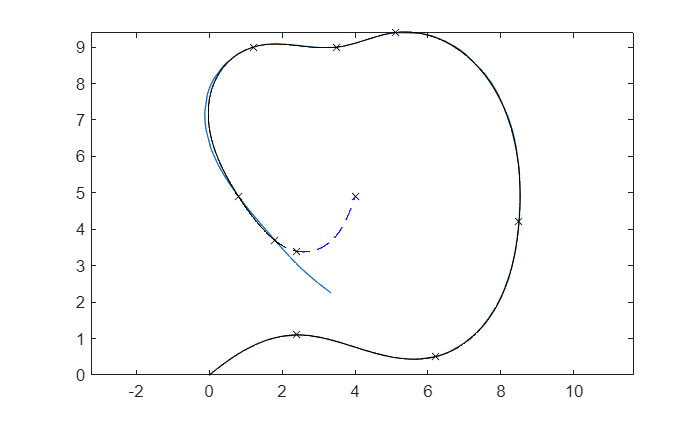

sol5 = bvp4c(@(t,s,times)ODEmain(t,s,times,r), @(so,sf,times)bcfunc(so,sf,times,r,city_sequence), sol5init);

hold on
plot(sol5.y(1,:), sol5.y(2,:), '-k', sol5.y(9,:), sol5.y(10,:), '-k', sol5.y(17,:), sol5.y(18,:), '-k', sol5.y(25,:), sol5.y(26,:), '-k', ...
    sol5.y(33,:), sol5.y(34,:), '-k', sol5.y(41,:), sol5.y(42,:), '-k', sol5.y(49,:), sol5.y(50,:), '-k', sol5.y(57,:), sol5.y(58,:), '-k', ...
    sol5.y(65,:), sol5.y(66,:), '--k', sol5.y(73,:), sol5.y(74,:), '--b')
axis equal

## Computation of time

Because the sol5.parameters values are the time durations for each individual path, they need to be summed together to compute the total time duration.

time = 0;
for i = 1:length(sol5.parameters)
    time = time + sol5.parameters(i); 
end
fprintf("time = %f", time)

time = 19.920597

## Plot of Final Solution

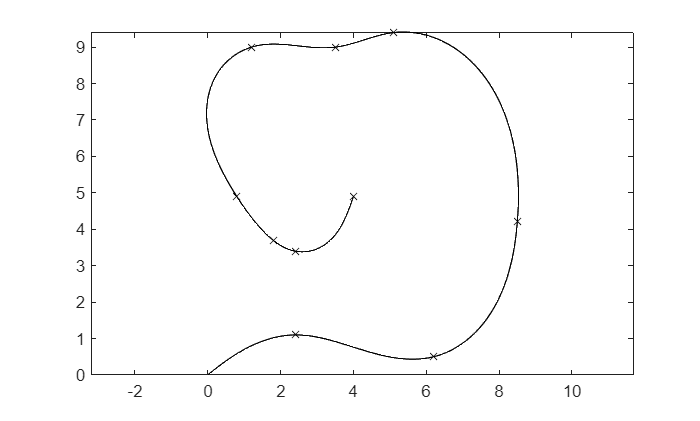

figure
plot(sol5.y(1,:), sol5.y(2,:), '-k', sol5.y(9,:), sol5.y(10,:), '-k', sol5.y(17,:), sol5.y(18,:), '-k', sol5.y(25,:), sol5.y(26,:), '-k', ...
    sol5.y(33,:), sol5.y(34,:), '-k', sol5.y(41,:), sol5.y(42,:), '-k', sol5.y(49,:), sol5.y(50,:), '-k', sol5.y(57,:), sol5.y(58,:), '-k', ...
    sol5.y(65,:), sol5.y(66,:), '-k', sol5.y(73,:), sol5.y(74,:), '-k', city_sequence(1,1:10),city_sequence(2,1:10),'xk')
axis equal

## Saving the Solution through All 10 Cities

solution.sol = sol5;
solution.city_sequence = city_sequence;
solution.r = r;
%save("ColonParenthesis_path.mat","solution")

This saved file is used in the Final_solution.mlx script to iterate through larger r values.

## Functions

This function computes the Hamiltonian using a "bang-bang" approximation of gamma and a.

function H = Hamiltonian(s,r) 

gamma = -(r/2)*s(7); 
if abs(gamma)>1 
    gamma = sign(gamma); 
end
a = -(r/2)*s(8); 
if abs(a) >1
    a = sign(a); 
end
H = 1 +(1/r)*(gamma^2 +a^2)+ s(5)*s(4)*cos(s(3))+s(6)*s(4)*sin(s(3))+s(7)*gamma+s(8)*a; 

end

This function returns the derivatives of all of the states and costates (lambdas). These dynamics are derived from Pontryagin's Minimum Principle. 

function ds = ODEs (~,s, r) 

% s(1) = x, s(2) = y, s(3) = theta, s(4) = v, s(5) = lambda_x, s(6) =
% lambda(y), s(7) = lambda_theta, s(8) = lambda_v

gamma = -(r/2)*s(7);
if abs(gamma) > 1
    gamma = sign(gamma); 
end
a = -(r/2)*s(8); 
if abs(a) > 1
    a = sign(a); 
end

ds(1,1) = s(4)*cos(s(3)); 
ds(2,1) = s(4)*sin(s(3)); 
ds(3,1) = gamma; 
ds(4,1) = a; 
ds(5,1) = 0; 
ds(6,1) = 0; 
ds(7,1) = s(5)*s(4)*sin(s(3)) - s(6)*s(4)*cos(s(3)); 
ds(8,1) = -s(5)*cos(s(3)) - s(6)*sin(s(3)); 

end

This function is designed for bvp4c, and it stacks several copies of the single-arc dynamics from ODEs to represent a trajectory of several arcs between cities. 

function ds = ODEmain(t,s,times, r) 

% s(8*i-7:8*i) arc i

ds = zeros(size(s)); % Preallocation for ds

for i = 1:length(times)
    ds(8*i-7:8*i, 1) = ODEs(t,s(8*i-7:8*i),r)*times(i);
end    

end

This is the function used by the first GA. The fitness serves as the cost that the ga wants to minimize.  The "weight" parameter applies a penalty on what we decide is important, in this case proximity to each city, the costates, and the Hamiltonian. Minimizing "fitness" means the best approximate trajectory from P0 to P1 to P2.

function fitness = fun1(x, r, P0, P1, P2) 
 
% x(1) = theta(0), x(2) = lambda_x(0), x(3) = lambda_y(0), x(4)= 
% lambda_v(0), x(5) = t1, x(6) = lambda_x(t1+), x(7) = lambda_y(t1+), x(8) =
% t2
% P0 = starting city, P1 = mid city, P2 = end city
[~, S1] = ode45(@(t,s)ODEs(t,s,r),  linspace(0, x(5), 11), [P0(1), P0(2), x(1), 0, x(2), x(3), 0, x(4)]); 
[~, S2] = ode45(@(t,s)ODEs(t,s,r), linspace(0, x(8),11), [S1(end,1:4), x(6), x(7), S1(end, 7:8)]);
weight = 10; % parameter that is placing a penalty on the distance

fitness = (x(5) + x(8)) ...
    + weight*((S1(end,1) - P1(1))^2 + (S1(end,2) - P1(2))^2) ... % city 1 distance
    + weight*((S2(end,1) - P2(1))^2 + (S2(end,2) - P2(2))^2) ... % city 2 distance
    + 10*(S2(end,7)^2 + S2(end,8)^2) ...
    + 10*Hamiltonian(S2(end, :), r)^2;

end

This function is similar to the function fun1, except that it uses the sol1 struct from the previous leg, so this function can be used for any path after the first one.

function fitness = fun2(x, r, sol1, P1, P2) 

% x(1) = lambda_x(t2+), x(2) = lambda_y(t2+), x(3) = t3, 
% x(4) = lambda_x(t3+), x(5) = lambda_y(t3+), x(6) = t4

[~, SX_1] = ode45(@(t,s)ODEs(t,s,r),  linspace(0, x(3), 11), [sol1.y(end-7,end), sol1.y(end-6,end), sol1.y(end-5,end), sol1.y(end-4,end), ...
        x(1), x(2), sol1.y(end-1,end), sol1.y(end,end)]); 
[~, SX_2] = ode45(@(t,s)ODEs(t,s,r), linspace(0, x(6),11), [SX_1(end,1:4), x(4), x(5), SX_1(end, 7:8)]);

weight = 10; % parameter that is placing a penalty on the distance
fitness = (x(3) + x(6)) ...
    + weight*((SX_1(end,1) - P1(1))^2 + (SX_1(end,2) - P1(2))^2) ...
    + weight*((SX_2(end,1) - P2(1))^2 + (SX_2(end,2) - P2(2))^2) ...
    + 10*(SX_2(end,7)^2 + SX_2(end,8)^2) ...
    + 10*Hamiltonian(SX_2(end, :), r)^2;
end

This function, designed for bvp4c and generalized for any path using a for loop, enforces the initial constraints, intermediate constraints (at each intermediate city), and transversality conditions required by Pontryagin's minimum principle. 

function con = bcfunc(so,sf,times,r,city_sequence) 

% s(1) = x, s(2) = y, s(3) = theta, s(4) = v, s(5) = lambda_x
% s(6) = lambda_y, s(7) = lambda_theta, s(8) = lambda_v

% Initial Constraints
con(1) = so(1); % x(0) = 0
con(2) = so(2); % y(0) = 0
con(3) = so(7); % lambda_theta(0) = 0
con(4) = so(4); % v(0) = 0

for i = 1:(length(times) - 1)
    con(9*i-4) = (sf(8*(i-1)+1) - city_sequence(1,i));                        % Intermediate Constraints
    con(9*i-3) = (sf(8*(i-1)+2) - city_sequence(2,i));                        % Intermediate Constraints
    con((9*i-2):(9*i+1)) = sf((8*(i-1)+1):(8*(i-1)+4)) - so((8*i+1):(8*i+4)); % Continuity (x,y,theta,v)
    con((9*i+2):(9*i+3)) = sf((8*(i-1)+7):(8*(i-1)+8)) - so((8*i+7):(8*i+8)); % Continuity (x,y,theta,v)
    con(9*i+4) = Hamiltonian(sf((8*(i-1)+1):(8*(i-1)+8)),r);                  % Transversality Conditions
end

% Terminal Constraints
con(9*i+5) = sf(8*i+1) - city_sequence(1,i+1);   % Final city x
con(9*i+6) = sf(8*i+2) - city_sequence(2,i+1); % Final city y
con(9*i+7) = sf(end-1);                        % lambda_theta(tf)
con(9*i+8) = sf(end);                          % lambda_v(tf)
con(9*i+9) = Hamiltonian(sf((8*i+1):(8*i+8)),r);

end

This function is the same as bcfunc, but it changes the terminal constraint for lambda_theta (sf(end-1)) to be a constraint for theta. In previous iterations, the solver wasn't able to find a solution if the final heading was too high, so we restricted the final theta to be 3.5 radians after several tests to find what worked. 

function con = homotopycity6(so,sf,times,r,city_sequence)

% s(1) = x, s(2) = y, s(3) = theta, s(4) = v, s(5) = lambda_x
% s(6) = lambda_y, s(7) = lambda_theta, s(8) = lambda_v

% Initial Constraints
con(1) = so(1); % x(0) = 0
con(2) = so(2); % y(0) = 0
con(3) = so(7); % lambda_theta(0) = 0
con(4) = so(4); % v(0) = 0

for i = 1:(length(times) - 1)
    con(9*i-4) = (sf(8*(i-1)+1) - city_sequence(1,i));                        % Intermediate Constraints
    con(9*i-3) = (sf(8*(i-1)+2) - city_sequence(2,i));                        % Intermediate Constraints
    con((9*i-2):(9*i+1)) = sf((8*(i-1)+1):(8*(i-1)+4)) - so((8*i+1):(8*i+4)); % Continuity (x,y,theta,v)
    con((9*i+2):(9*i+3)) = sf((8*(i-1)+7):(8*(i-1)+8)) - so((8*i+7):(8*i+8)); % Continuity (x,y,theta,v)
    con(9*i+4) = Hamiltonian(sf((8*(i-1)+1):(8*(i-1)+8)),r);                  % Transversality Conditions
end

% Terminal Constraints
con(9*i+5) = sf(8*i+1) - city_sequence(1,i+1); % Final city x
con(9*i+6) = sf(8*i+2) - city_sequence(2,i+1); % Final city y
con(9*i+7) = sf(end-5) - 3.5;                  % HOMOTOPY where we limit theta(t6-) to 3.5 radians
con(9*i+8) = sf(end);                          % lambda_v(tf)
con(9*i+9) = Hamiltonian(sf((8*i+1):(8*i+8)),r);

end